## 데이터 로드

clear; close all; clc;

load('DREAMER.mat');

% 파라미터 초기화
EEG_SamplingRate = 128;
ECG_SamplingRate = 256;
ch_n = 14;

wnd_size = [-1 4];
baseline = [-1 0];
f_scale = 1;
freq_band = [0.1 100];

fullscreen = get(0, 'ScreenSize');

electrode_pos = [
    0.2, 0.8;   % AF3
    0.1, 0.7;   % F7
    0.2, 0.7;   % F3
    0.3, 0.6;   % FC5
    0.1, 0.5;   % T7
    0.2, 0.4;   % P7
    0.3, 0.3;   % O1
    0.7, 0.3;   % O2
    0.8, 0.4;   % P8
    0.9, 0.5;   % T8
    0.7, 0.6;   % FC6
    0.8, 0.7;   % F4
    0.9, 0.7;   % F8
    0.8, 0.8;   % AF4
];

% 데이터 추출
all_EEG_data = {};
all_labels = [];
all_ECG_data = {};

for i = 1:DREAMER.noOfSubjects
    for j = 1:DREAMER.noOfVideoSequences
        EEG_data = DREAMER.Data{i}.EEG.stimuli{j}; % M x 14 행렬
        ECG_data = DREAMER.Data{i}.ECG.stimuli{j};  % M x 2 행렬

        valence = DREAMER.Data{i}.ScoreValence(j);
        arousal = DREAMER.Data{i}.ScoreArousal(j);
        dominance = DREAMER.Data{i}.ScoreDominance(j);

        all_EEG_data{end+1} = EEG_data;
        all_labels = [all_labels; valence, arousal, dominance];
        all_ECG_data{end+1} = ECG_data;
    end
end

save('all_EEG_data.mat', 'all_EEG_data');
save('all_labels.mat', 'all_labels');
save('all_ECG_data.mat', 'all_ECG_data');

% 데이터 체크
% disp(all_EEG_data{1})
% disp(all_labels(1, :))

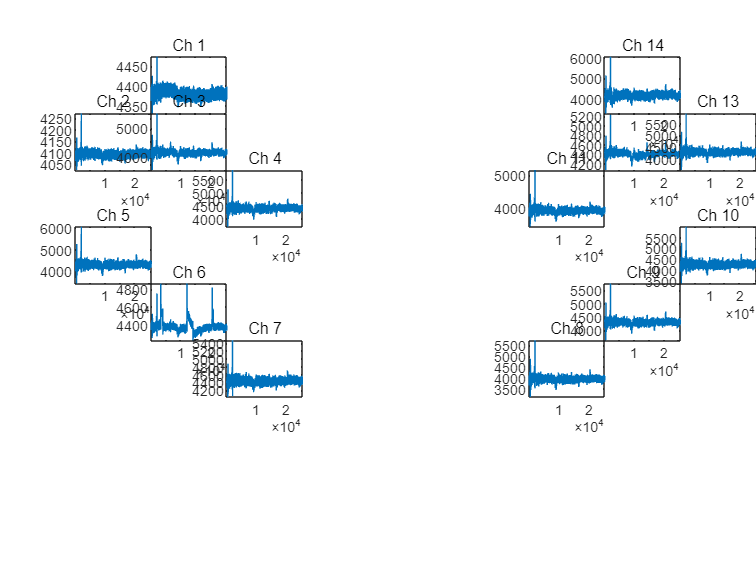

EEG_data = DREAMER.Data{1}.EEG.stimuli{1};  % M x 14 행렬

% 데이터 plotting 
figure;
hold on;

for ch = 1 : ch_n
    x_pos = electrode_pos(ch, 1);
    y_pos = electrode_pos(ch, 2);
    
    subplot('Position', [x_pos, y_pos, 0.1, 0.1]);
    plot(EEG_data(:, ch));
    axis tight;
    title(sprintf('Ch %d', ch));
end

hold off;

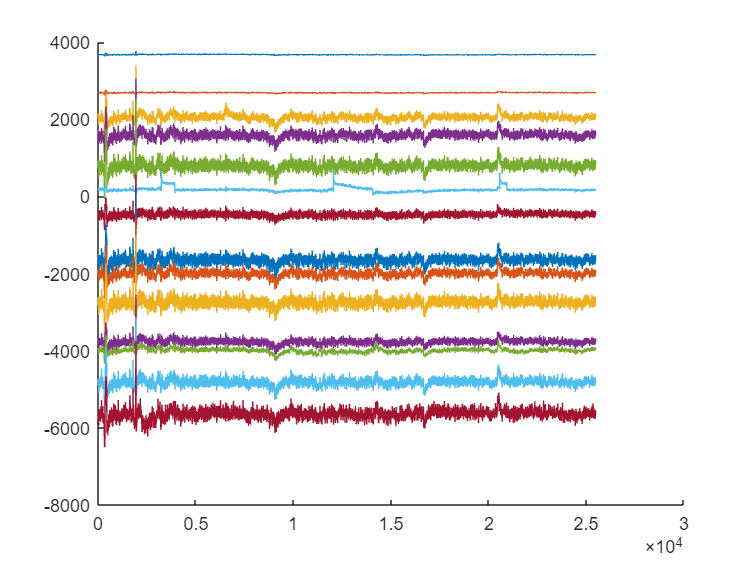

figure; hold on;
for ch = 1:ch_n
    plot(EEG_data(:, ch) - ch * 700);
end
hold off;

## 데이터 전처리

### CAR

% CAR
for idx = 1:length(all_EEG_data)
    EEG_data = all_EEG_data{idx};
    
    mean_data = mean(EEG_data, 2);

    EEG_data_CAR = EEG_data - mean_data;
    
    all_EEG_data_CAR{idx} = EEG_data_CAR;
end


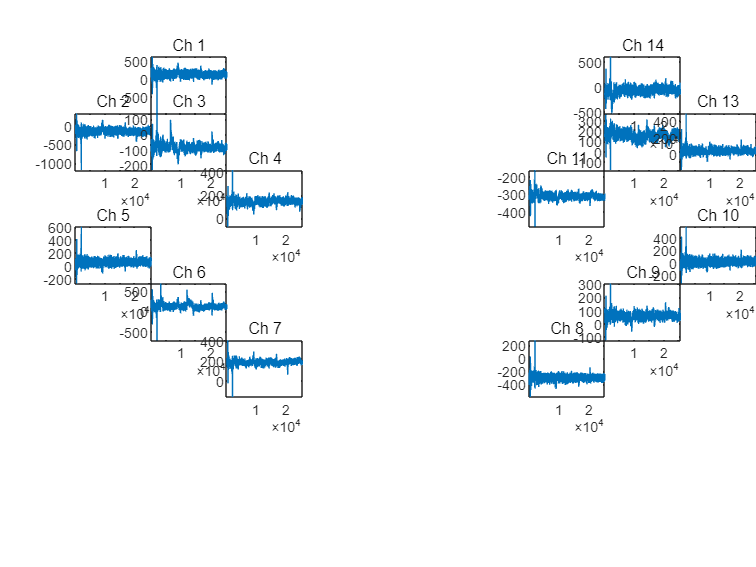

EEG_data_CAR = all_EEG_data_CAR{1};  % M x 14 행렬

figure;
hold on;

for ch = 1 : ch_n
    x_pos = electrode_pos(ch, 1);
    y_pos = electrode_pos(ch, 2);

    subplot('Position', [x_pos, y_pos, 0.1, 0.1]);
    plot(EEG_data_CAR(:, ch));
    axis tight;
    title(sprintf('Ch %d', ch));
end

hold off;

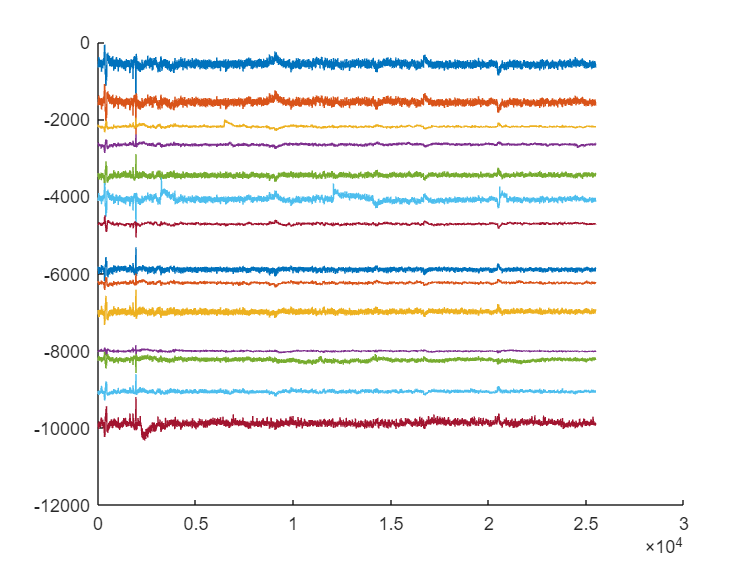

figure; hold on;
for ch = 1:ch_n
    plot(EEG_data_CAR(:, ch) - ch * 700);
end
hold off;

save('all_EEG_data_CAR.mat', 'all_EEG_data_CAR');

### Artifact 제거

% for subject = 1:DREAMER.noOfSubjects
%     screenSize = get(0, 'ScreenSize'); 
%     fig = figure('Name', sprintf('Subject %d - All Trials', subject), 'Position', [0, 0, screenSize(3), screenSize(4)]);
% 
%     rows = 6;
%     cols = 3;
% 
%     for trial = 1:DREAMER.noOfVideoSequences
%         EEG_data = all_EEG_data{(subject - 1) * DREAMER.noOfVideoSequences + trial};
% 
%         subplot(rows, cols, trial);
%         hold on;
% 
%         for ch = 1:ch_n
%             plot(EEG_data(:, ch) - ch * 700);
%         end
% 
%         title(sprintf('Subject %d - Trial %d', subject, trial));
%         hold off;
%     end
% 
%     filename = sprintf('CAR_Subject_%d.jpg', subject);
% 
%     exportgraphics(fig, filename, 'Resolution', 300);
% 
%     close(fig);
% end

load('all_EEG_data_CAR.mat');
size(all_EEG_data_CAR);

EEG_1 = all_EEG_data_CAR{1};

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\wooyo\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
You are using the latest version of EEGLAB.


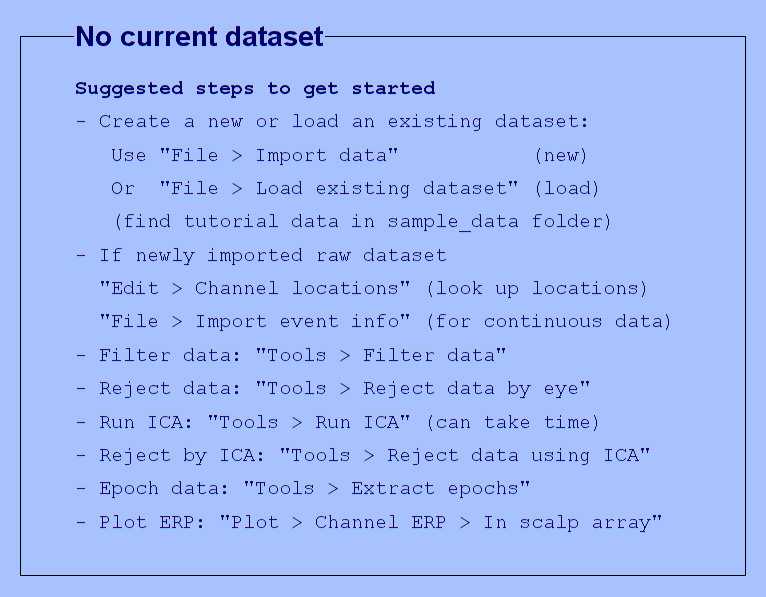

eeglab;